%Timing of excitation and inhibition in preferred and null direction
ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

epochTime = 5.5; %seconds
exc_PD_Ups = zeros(0, epochTime*1000);
inh_PD_Ups = zeros(0, epochTime*1000);
exc_Null_Ups = zeros(0, epochTime*1000);
inh_Null_Ups = zeros(0, epochTime*1000);

exc_PD_Downs = zeros(0, epochTime*1000);
inh_PD_Downs = zeros(0, epochTime*1000);
exc_Null_Downs = zeros(0, epochTime*1000);
inh_Null_Downs = zeros(0, epochTime*1000);

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'Intracellular'}; %child field name should be one of these. Priority is in given order
priorityOrder_2c = {'_ff'; 'Extracellular'};
mustHave_1 = [];
mustHave_2 = {'Intracellular', 'Excitation'};
mustHave_2b = {'Intracellular', 'Inhibition'};
mustHave_2c = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
cantHave_2c = {'Intracellular', 'Potassium'};
rigMandates = []; %

allDirections = [0:45:315];
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};

    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    [loc_extracellular, pass3] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2c, mustHave_2c, cantHave_2c, rigMandates);
    if pass1 || pass2 || pass3
        continue
    end
    
    pd = loc_extracellular.Analysis_Results.PreferredDirection;
    [~, roundedPD_index] = min(abs(pd-allDirections));
    roundedPD = allDirections(roundedPD_index);
    roundedNull = mod(roundedPD-180, 360);
    
    excMeans = loc_excitation.Analysis_Results.meanTracesByOrientation;
    inhMeans = loc_inhibition.Analysis_Results.meanTracesByOrientation;
    
    excitationPD_index = excMeans.orientationOrder == roundedPD;
    excitationNull_index = excMeans.orientationOrder == roundedNull;
    inhibitionPD_index = inhMeans.orientationOrder == roundedPD;
    inhibitionNull_index = inhMeans.orientationOrder == roundedNull;
    
    exc_PD_Ups(end + 1, :) = excMeans.meanTraces(excitationPD_index, :);
    exc_Null_Ups(end + 1, :) = excMeans.meanTraces(excitationNull_index, :);
    inh_PD_Ups(end + 1, :) = inhMeans.meanTraces(inhibitionPD_index, :);
    inh_Null_Ups(end + 1, :) = inhMeans.meanTraces(inhibitionNull_index, :);
end

for i = 1:size(downs, 1)
    struct_i = downs{i, 2};

    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    [loc_extracellular, pass3] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2c, mustHave_2c, cantHave_2c, rigMandates);
    if pass1 || pass2 || pass3
        continue
    end
    
    pd = loc_extracellular.Analysis_Results.PreferredDirection;
    [~, roundedPD_index] = min(abs(pd-allDirections));
    roundedPD = allDirections(roundedPD_index);
    roundedNull = mod(roundedPD-180, 360);
    
    excMeans = loc_excitation.Analysis_Results.meanTracesByOrientation;
    inhMeans = loc_inhibition.Analysis_Results.meanTracesByOrientation;
    
    excitationPD_index = excMeans.orientationOrder == roundedPD;
    excitationNull_index = excMeans.orientationOrder == roundedNull;
    inhibitionPD_index = inhMeans.orientationOrder == roundedPD;
    inhibitionNull_index = inhMeans.orientationOrder == roundedNull;
    
    exc_PD_Downs(end + 1, :) = excMeans.meanTraces(excitationPD_index, :);
    exc_Null_Downs(end + 1, :) = excMeans.meanTraces(excitationNull_index, :);
    inh_PD_Downs(end + 1, :) = inhMeans.meanTraces(inhibitionPD_index, :);
    inh_Null_Downs(end + 1, :) = inhMeans.meanTraces(inhibitionNull_index, :);
end

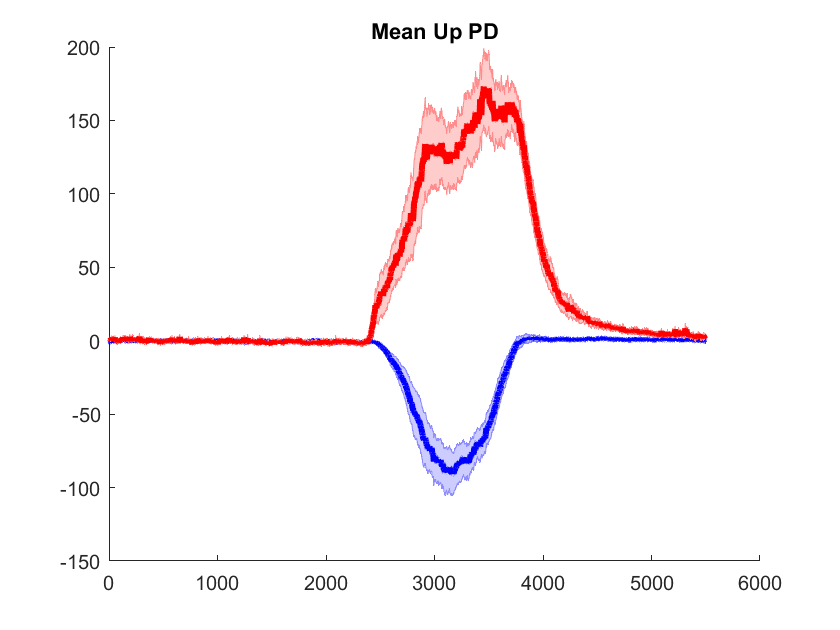

smoothWindow = 30; %in ms, the window length to smooth the recorded traces by (movmean) in order to get peak values for timing
upPeakExTimes_PD = [];
upPeakExTimes_ND = [];
upPeakDiffs_PD = [];
upPeakDiffs_ND = [];
for i = 1:size(exc_PD_Ups, 1)
    %calculate the difference between peak excitation and peak inhibition
    PD_ex_i = exc_PD_Ups(i, :);
    PD_inh_i = inh_PD_Ups(i, :);
    [~, indx_ex] = min(movmean(PD_ex_i, smoothWindow));
    [~, indx_inh] = max(movmean(PD_inh_i, smoothWindow));
    upPeakDiffs_PD(end+1) = indx_ex - indx_inh; %timing difference in peaks for pd (ms)
    upPeakExTimes_PD(end + 1) = indx_ex;

    ND_ex_i = exc_Null_Ups(i, :);
    ND_inh_i = inh_Null_Ups(i, :);
    [~, indx_ex] = min(movmean(ND_ex_i, smoothWindow));
    [~, indx_inh] = max(movmean(ND_inh_i, smoothWindow));
    upPeakDiffs_ND(end+1) = indx_ex - indx_inh; %timing difference in peaks for pd (ms)
    upPeakExTimes_ND(end + 1) = indx_ex;
    
%     figure
%     subplot(2, 1, 1)
%     title('Preferred Direction (Up Cell)')
%     hold on
%     plot(PD_ex_i, 'b')
%     plot(PD_inh_i, 'g')
%     hold off
%     subplot(2, 1, 2)
%     title('Null Direction')
%     hold on
%     plot(ND_ex_i, 'b')
%     plot(ND_inh_i, 'g')
end

downPeakExTimes_PD = [];
downPeakExTimes_ND = [];
downPeakDiffs_PD = [];
downPeakDiffs_ND = [];
for i = 1:size(exc_PD_Downs, 1)
    PD_ex_i = exc_PD_Downs(i, :);
    PD_inh_i = inh_PD_Downs(i, :);
    [~, indx_ex] = min(movmean(PD_ex_i, smoothWindow));
    [~, indx_inh] = max(movmean(PD_inh_i, smoothWindow));
    downPeakDiffs_PD(end+1) = indx_ex - indx_inh; %timing difference in peaks for pd (ms)
    downPeakExTimes_PD(end + 1) = indx_ex;

    ND_ex_i = exc_Null_Downs(i, :);
    ND_inh_i = inh_Null_Downs(i, :);
    [~, indx_ex] = min(movmean(ND_ex_i, smoothWindow));
    [~, indx_inh] = max(movmean(ND_inh_i, smoothWindow));
    downPeakDiffs_ND(end+1) = indx_ex - indx_inh; %timing difference in peaks for pd (ms)
    downPeakExTimes_ND(end + 1) = indx_ex;

%     figure
%     subplot(2, 1, 1)
%     title('Preferred Direction (Down Cell)')
%     hold on
%     plot(PD_ex_i, 'b')
%     plot(PD_inh_i, 'g')
%     hold off
%     subplot(2, 1, 2)
%     title('Null Direction')
%     hold on
%     plot(ND_ex_i, 'b')
%     plot(ND_inh_i, 'g')
end
SEM = @(x) std(x)./sqrt(size(x, 1));
timeVector = [1:size(exc_PD_Ups, 2)];
figure
title('Mean Up PD')
hold on
shadedErrorBar(timeVector, mean(exc_PD_Ups), SEM(exc_PD_Ups), 'LineProps', {'b', 'LineWidth', 3})
shadedErrorBar(timeVector, mean(inh_PD_Ups), SEM(inh_PD_Ups), 'LineProps', {'r', 'LineWidth', 3})

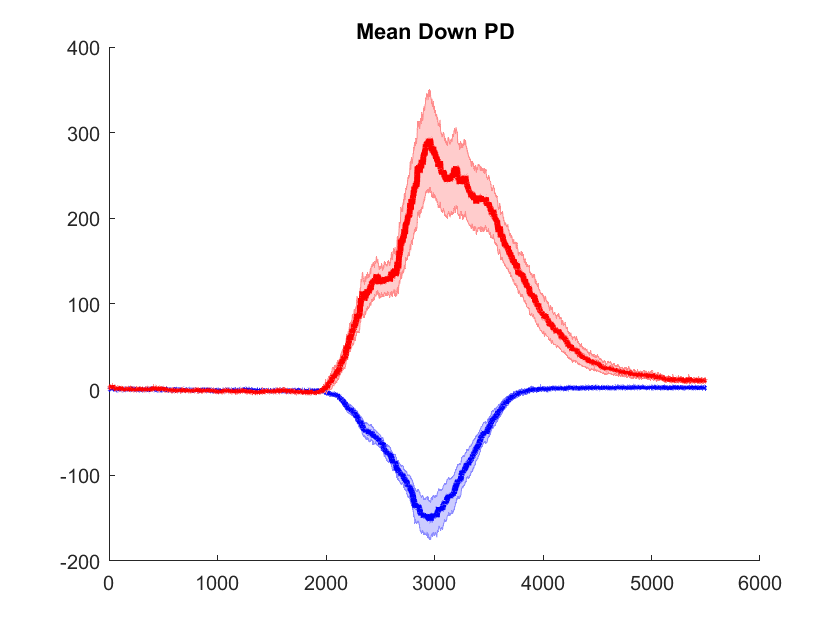


figure
title('Mean Down PD')
hold on
shadedErrorBar(timeVector, mean(exc_PD_Downs), SEM(exc_PD_Downs), 'LineProps', {'b', 'LineWidth', 3})
shadedErrorBar(timeVector, mean(inh_PD_Downs), SEM(inh_PD_Downs), 'LineProps', {'r', 'LineWidth', 3})

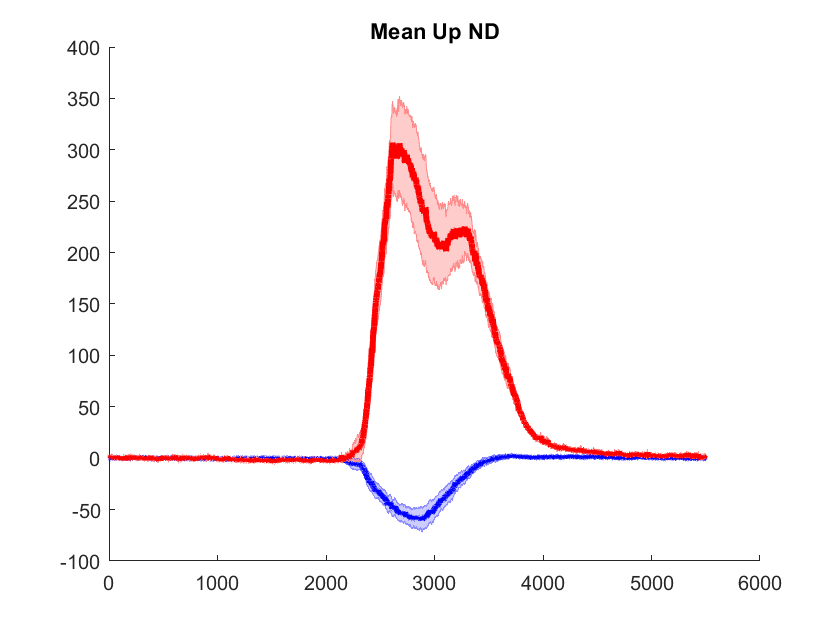


figure
title('Mean Up ND')
hold on
shadedErrorBar(timeVector, mean(exc_Null_Ups), SEM(exc_Null_Ups), 'LineProps', {'b', 'LineWidth', 3})
shadedErrorBar(timeVector, mean(inh_Null_Ups), SEM(inh_Null_Ups), 'LineProps', {'r', 'LineWidth', 3})

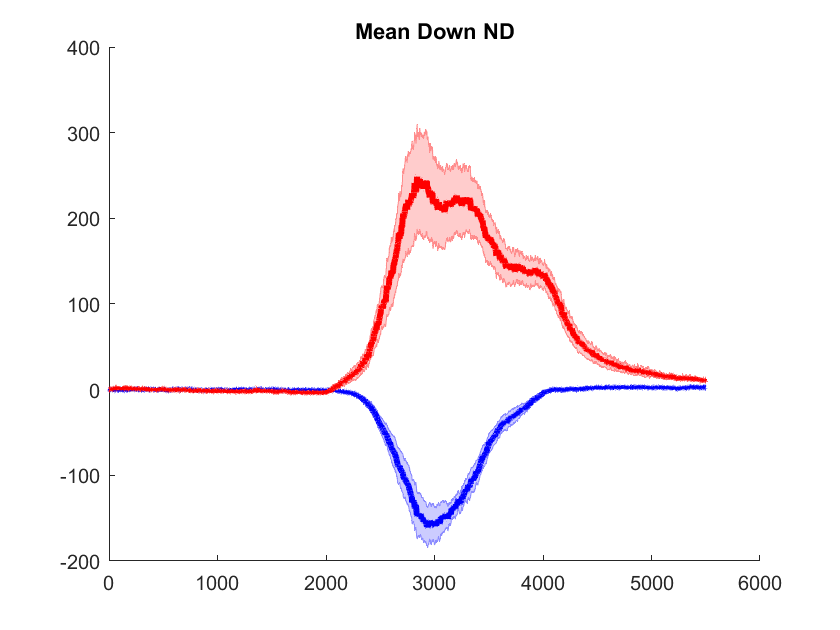


figure
title('Mean Down ND')
hold on
shadedErrorBar(timeVector, mean(exc_Null_Downs), SEM(exc_Null_Downs), 'LineProps', {'b', 'LineWidth', 3})
shadedErrorBar(timeVector, mean(inh_Null_Downs), SEM(inh_Null_Downs), 'LineProps', {'r', 'LineWidth', 3})

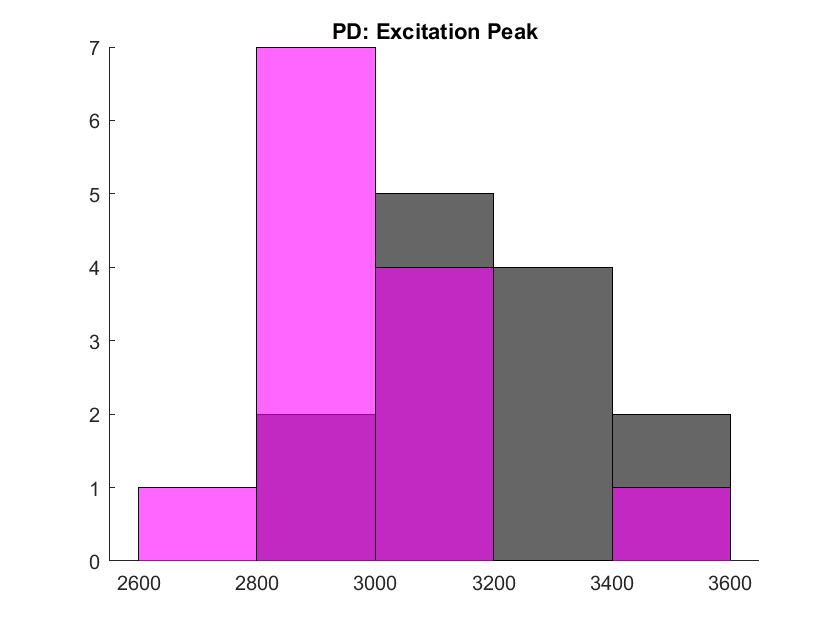


figure
title('PD: Excitation Peak')
hold on
h1 = histogram(upPeakExTimes_PD, 'FaceColor', 'k');
h2 = histogram(downPeakExTimes_PD, 'FaceColor', 'm');
h2.BinWidth = h1.BinWidth;

p = ranksum(upPeakExTimes_PD, downPeakExTimes_PD)

p = 0.0071

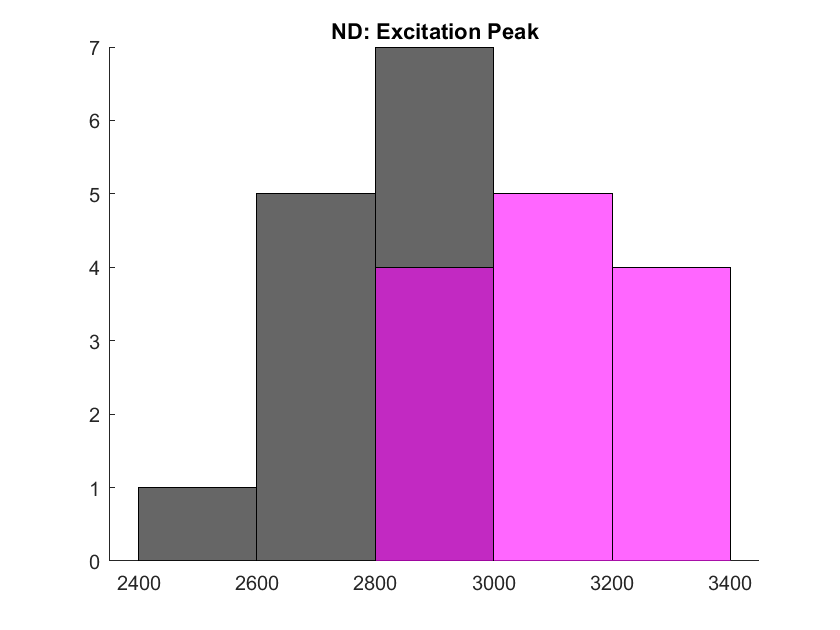


figure
title('ND: Excitation Peak')
hold on
h1 = histogram(upPeakExTimes_ND, 'FaceColor', 'k');
h2 = histogram(downPeakExTimes_ND, 'FaceColor', 'm');
h2.BinWidth = h1.BinWidth;

p = ranksum(upPeakExTimes_ND, downPeakExTimes_ND)

p = 7.8571e-05

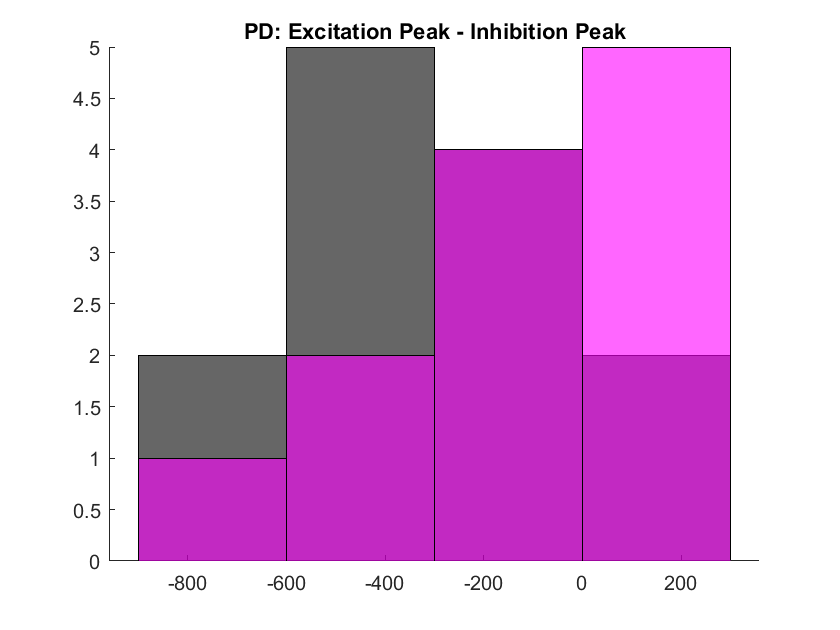


figure
title('PD: Excitation Peak - Inhibition Peak')
hold on
h1 = histogram(upPeakDiffs_PD, 'FaceColor', 'k');
h2 = histogram(downPeakDiffs_PD, 'FaceColor', 'm');
h2.BinEdges = h1.BinEdges;

p = ranksum(upPeakDiffs_PD, downPeakDiffs_PD)

p = 0.0812

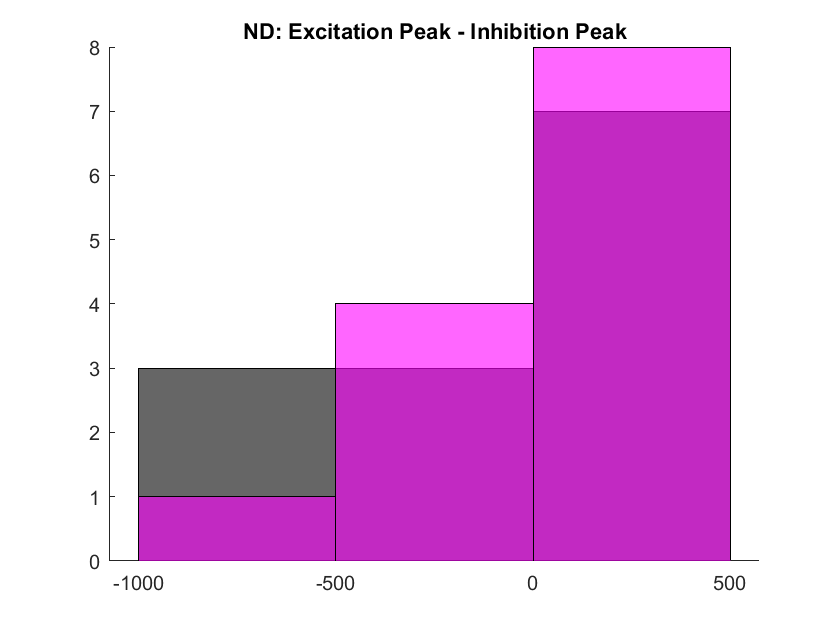


figure
title('ND: Excitation Peak - Inhibition Peak')
hold on
h1 = histogram(upPeakDiffs_ND, 'FaceColor', 'k');
h2 = histogram(downPeakDiffs_ND, 'FaceColor', 'm');
h2.BinEdges = h1.BinEdges;

p = ranksum(upPeakDiffs_ND, downPeakDiffs_ND)

p = 0.7196